%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% All rights reserved by Krishna Pillai, http://www.dsplog.com
% The file may not be re-distributed without explicit authorization
% from Krishna Pillai.
% Checked for proper operation with Octave Version 3.0.0
% Author        : Krishna Pillai
% Email         : krishna@dsplog.com
% Version       : 1.0
% Date          : 18 August 2008
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Script for computing the BER for BPSK modulation in a
% AWGN channel with receive diversity

clear
N = 10^6 % number of bits or symbols

N = 1000000

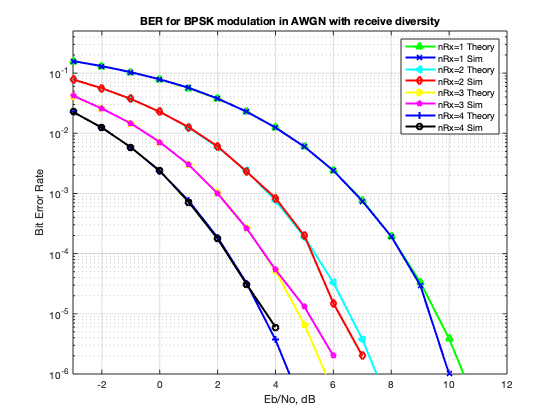


% Transmitter
ip = rand(1,N)>0.5; % generating 0,1 with equal probability
s = 2*ip-1; % BPSK modulation 0 -> -1; 1 -> 0


Eb_N0_dB = [-3:15]; % multiple Eb/N0 values

nRx = [1 2 3 4]; % number of receive antenna


for jj = 1:length(nRx)
    for ii = 1:length(Eb_N0_dB)

        n = 1/sqrt(2)*[randn(nRx(jj),N) + j*randn(nRx(jj),N)]; % white gaussian noise, 0dB variance on each row

        % Noise addition
        y = ones(nRx(jj),1)*s + 10^(-Eb_N0_dB(ii)/20)*n;

        % equalization
        yHat = sum(y,1)/nRx(jj);

        % receiver - hard decision decoding
        ipHat = real(yHat)>0;

        % counting the errors
        nErr(jj,ii) = size(find([ip- ipHat]),2);
    end
    TheoryBerAWGN(jj,:) = 0.5*erfc(sqrt(nRx(jj)*10.^(Eb_N0_dB/10))); % theoretical ber    

end

SimBer = nErr/N; % Simulated ber

% plot
close all
figure
semilogy(Eb_N0_dB,TheoryBerAWGN(1,:),'g-^','LineWidth',2);
hold on
semilogy(Eb_N0_dB,SimBer(1,:),'bx-','LineWidth',2);
semilogy(Eb_N0_dB,TheoryBerAWGN(2,:),'c-<','LineWidth',2);
semilogy(Eb_N0_dB,SimBer(2,:),'rd-','LineWidth',2);
semilogy(Eb_N0_dB,TheoryBerAWGN(3,:),'y->','LineWidth',2);
semilogy(Eb_N0_dB,SimBer(3,:),'mp-','LineWidth',2);
semilogy(Eb_N0_dB,TheoryBerAWGN(4,:),'b+-','LineWidth',2);
semilogy(Eb_N0_dB,SimBer(4,:),'ko-','LineWidth',2);
axis([-3 12 10^-6 0.5])
grid on
legend('nRx=1 Theory','nRx=1 Sim', 'nRx=2 Theory','nRx=2 Sim','nRx=3 Theory','nRx=3 Sim','nRx=4 Theory','nRx=4 Sim');
xlabel('Eb/No, dB');
ylabel('Bit Error Rate');
title('BER for BPSK modulation in AWGN with receive diversity');